5. Dado el sistema,


$$\dot x_1 = -x_1 (1 - x_1^2 - x_2^2) + x_2\\
\dot x_2 = -x_2 (1 - x_1^2 - x_2^2) - x_1,\\$$


a) Obtener un diagrama de fases del sistema, empleando para ello Matlab. Comprobar gráficamente que el círculo $x_1^2 +x_2^2 =1$ marca el límite de la región de estabilidad del punto de equilibrio del sistema (0, 0). Pista: una manera clara de obtener el resultado es integrar para un intervalo de tiempo negativo, en ese caso, el límite de estabilidad se convierte en un ciclo límite.

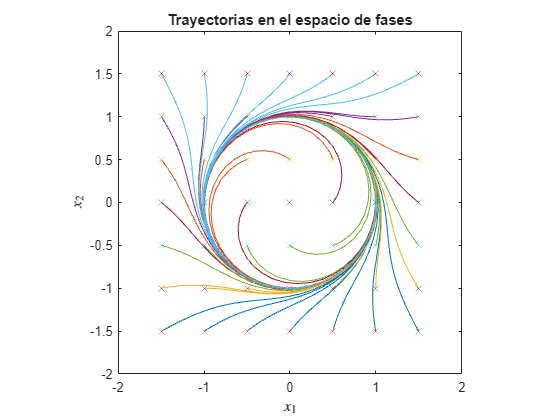

x1 = -1.5:0.5:1.5;
x2 = x1;

t_range = [0,-10];

figure
clf
for i = 1:length(x1)
    for j = 1:length(x2)
            [t,x] = ode45(@(t,x)system_ex5(t,x),t_range,[x1(i);x2(j)]);
            plot(x(:,1), x(:,2))
            hold on
            plot(x1(i), x2(j), 'x')
            clear x t
    end
end
daspect([1 1 1])
xlim([-2 2])
ylim([-2 2])
title('Trayectorias en el espacio de fases')
xlabel('$x_1$', 'interpreter', 'latex')
ylabel('$x_2$', 'interpreter', 'latex')

b) Comprobar que el resultado de integrar el sistema para un tiempo negativo es idéntico a obtener las soluciones del sistema presentado en el ejemplo 2.4.7 (ver manual de apuntes), tomando $\mu =1$. 

El sistema a comparar es el siguiente:


$$\dot x_1 = x_1 (1 - x_1^2 - x_2^2) - x_2\\
\dot x_2 = x_2 (1 - x_1^2 - x_2^2) + x_1.\\$$


Con el código a continuación se comprueba la hipótesis planteada. Además, analizando las ecuaciones de ambos sistemas, se puede apreciar que la única diferencia que existe entre ellos es el signo global de las variaciones de las variables. Esto implica que si $\mathrm{d}t$ cambia de signo, tal y como se ha hecho en el primer apartado, el sistema es equivalente al segundo.

x1 = -1.5:0.5:1.5;
x2 = x1;

t_range = [0,10];

figure
clf
for i = 1:length(x1)
    for j = 1:length(x2)
            [t,x] = ode45(@(t,x)system_ex5b(t,x),t_range,[x1(i);x2(j)]);
            plot(x(:,1), x(:,2))
            hold on
            plot(x1(i), x2(j), 'x')
            clear x t
    end
end
daspect([1 1 1])
xlim([-2 2])
ylim([-2 2])
title('Trayectorias en el espacio de fases')
xlabel('$x_1$', 'interpreter', 'latex')
ylabel('$x_2$', 'interpreter', 'latex')

function xdot = system_ex5(t, x)
    xdot(1,1) = -x(1,1)*(1-x(1,1)^2-x(2,1)^2) + x(2,1);
    xdot(2,1) = -x(2,1)*(1-x(1,1)^2-x(2,1)^2) - x(1,1);
end

function xdot = system_ex5b(t, x)
    xdot(1,1) = x(1,1)*(1-x(1,1)^2-x(2,1)^2) - x(2,1);
    xdot(2,1) = x(2,1)*(1-x(1,1)^2-x(2,1)^2) + x(1,1);
end